# **Analysis 1: Live cell analysis**

**Testing for:**

**YFP1: chromatin-bound MCM2**

**FarRed1: chromatin-bound PCNA**

## **Load Data**

[file_loc] = fileparts(matlab.desktop.editor.getActiveFilename);
cd(file_loc);
dataDir = 'F:\Data\C-Cdt1\Figures\Dryad\Data\';
%%% Experiment Paremeters %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
conditions = {
%     'DMSO',2,2,1:9,[0 0 0]; %1
         'DMSO',5:7,2:6,1:9,[0 0 0]; %1
         'DOX',5:7,7:11,1:9,[0 0 0]; %1

    };



load([dataDir filesep 'C221_data.mat'],'S');
% S = loadData(conditions, dataDir);
framesPerHr = 60/3;
frameDrugAdded = 0;                                                  
frameEdU = 0;
folding = 0;

numFrames = size(S(1).area,2);
xFrames = 1:numFrames; 
xTime = (xFrames-1)./framesPerHr;
 
map = nikon_well_offset_new(conditions,9,1);
POI_time = arrayfun(@(x) (numFrames - x.POI + repmat(cell2mat(map.values(x.shot)),1,size(x.POI,2)))/framesPerHr, S,'UniformOutput',false);
[S.POI_time] = POI_time{:};

**Set thresholds**

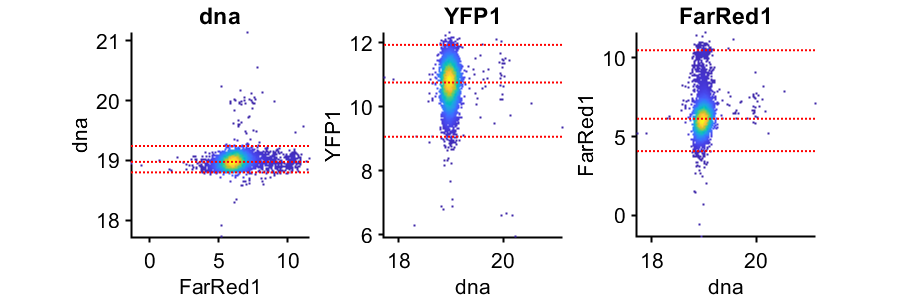

%% set G1 phase gates
cond=1;
gates = {'dna','YFP1','FarRed1'};
plotting = {'FarRed1','dna','dna'};
prctiles = {[1 50 99],[1 50 99],[1 50 99]};

figure('pos',[0 0 length(gates)*300 300 ])

for i = 1:length(gates)
    inds = S(cond).POI_time(:,1) > .5 & S(cond).POI_time(:,1) < 1  ;
    ydata = S(cond).(gates{i})(inds,:);
    xdata = S(cond).(plotting{i})(inds,:);
    
    gate.([gates{i} '_G1']) = prctile(ydata, prctiles{i});
    
    subplot(1,length(gates),i)
    dscatter(log2(xdata),log2(ydata));
    hline( log2(gate.([gates{i} '_G1'])))
    
    ylabel(gates{i});
    xlabel(plotting{i});
    title(gates{i});
    
end

conds=[1 1 2 1 2];
rng(1)
test = {};
ally = [];
group = [];
for i = 1:length(conds)
    condition = conds(i);
    ydata = log2(S(condition).YFP1);
    
    if ismember(i,[2 3 ])
        %early S DMSO
        inds = S(condition).POI(:,1) <= 1 * framesPerHr & (S(condition).POI_time(:,3)) <=1;
    elseif ismember(i,[4 5])
        % inhibited G1 DOX
        inds = S(condition).POI_time(:,1) <= 1 & S(condition).POI_time(:,1) >=.5;
    elseif ismember(i,[1])
        %G2
         inds = S(condition).allDNA > 2^19.6 & S(condition).allFarRed1 < 2^8;
        ydata = log2(S(condition).allYFP1);
    end
    
    ydata = ydata(inds);

    
    ydata = randsample(ydata,min([length(ydata), 1000]));
    %     ydata(ydata<1) = 1;
    test{i} = ydata;
    ally = [ally; ydata];
    group = [group; repmat(i,size(ydata))];
    meds(i) = median(ydata);
    
end
meds

meds =     5.9353   11.4565   10.7643   10.7666    6.3567    5.9591


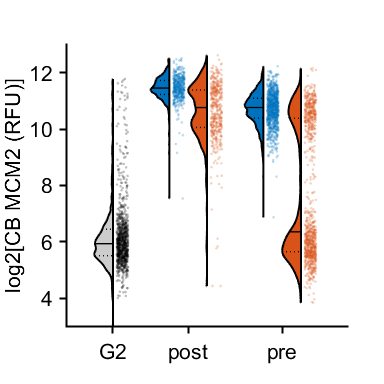

% figure;

% [h,p,ci,stats] = ttest2((test{1}),(test{2}))
% notBoxPlot((ally),group)
group_list = 1:max(group)+1;
offsetx = floor((group_list - 1)/2) * .5;
xkey = group_list(1:end-1) + offsetx(2:end);

figure('Units', 'Inches', 'Position', [0, 0, 4, 4])
h = violinPlot((ally),'groups',group, 'showMM',6,'histOpt',1,'divFactor',2,'histOri','left','widthDiv',[2 1],...
    'xNames',{'G2','DMSO S','DOX S ', 'G1 DMSO','G1 DOX'},'xValues',xkey,'distWidth',.8);
set(h{1},'EdgeColor',[0 0 0],'LineWidth',1.5)
hold on
cols = lines(2);
groupcol = [[0 0 0]; cols([1 2],:);cols([1 2],:)];
set(h{1},{'FaceColor'},{[.8 .8 .8],cols(1,:),cols(2,:),cols(1,:),cols(2,:)}')
hold on
jit = 0.3*rand(size(group)) + .1;
scatter(xkey(group)'+jit, (ally), 4,groupcol(group,:),'filled','MarkerFaceAlpha',.25);
ylabel('log2[CB MCM2 (RFU)]')
xticks([1 xkey(2:2:length(xkey)-1)+.5])
xticklabels({'G2','post','pre'})
ylim([ 3 13 ])
% hline(2^7.5)
% xtickangle(45)
axis square
print_pdf([pwd() '\Figs\mcm2_compare_scatter_extra_extra.pdf'])

splitapply(@length,ally,group)

ans =         1000
         468
         434
        1000
        1000
